clear;
for i = 1:3
    for j = 1:3
        for k = 1:5
            A(i,j,k) = i + 2*j;
        end
    end
end

A

A = A(:,:,1) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,2) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,3) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,4) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,5) =

     3     5     7
     4     6     8
     5     7     9



B = reshape(A,[],5)

B =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     7     7     7     7     7
     8     8     8     8     8
     9     9     9     9     9



clear;
M = 50;
N = ceil(M/2);
orig_dom_X1 = linspace(-pi/2,pi/2,M);
orig_dom_Y1 = linspace(-pi/2,pi/2,N)

orig_dom_Y1 =    -1.5708   -1.4399   -1.3090   -1.1781   -1.0472   -0.9163   -0.7854   -0.6545   -0.5236   -0.3927   -0.2618   -0.1309         0    0.1309    0.2618    0.3927    0.5236    0.6545    0.7854    0.9163    1.0472    1.1781    1.3090    1.4399    1.5708


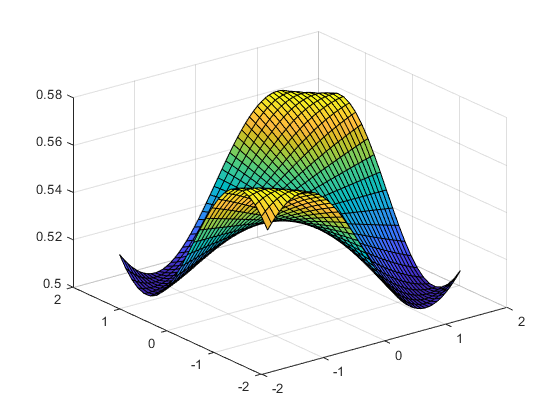

[X,Y] = ndgrid(orig_dom_X1,orig_dom_Y1);

for i = 1:88
    m = rand;
    b = rand;
    A(:,:,i) = m*sin(X.*Y) + b;
end
surf(X,Y,A(:,:,5))


s = size(A);

B = reshape(A,[],s(end))

B =     0.9603    0.9626    0.3924    0.9868    0.5538    1.3964    1.3895    1.3707    1.3107    0.6969    0.3058    0.9855    1.1881    0.1869    1.2485    1.1763    0.8368    0.6398    1.0656    1.3411    0.5445    0.6927    0.5975    0.8916    0.3823    1.1067    0.8917    1.2102    0.6138    0.7507    0.9139    0.4856    0.7673    0.6323    0.9150    0.9048    1.2010    1.1021    0.7414    1.1108    0.7373    1.1057    0.7267    0.9386    0.7565    0.3683    0.9937    1.2521    0.4345    0.7676
    0.9996    1.0173    0.4218    1.0370    0.5562    1.4626    1.4432    1.4212    1.3764    0.7487    0.3135    1.0216    1.2250    0.1905    1.2809    1.2078    0.8600    0.7109    1.0828    1.3999    0.6051    0.7072    0.6636    0.9596    0.4162    1.1376    0.9609    1.2615    0.6629    0.7888    0.9468    0.5042    0.7787    0.6734    0.9160    0.9789    1.2456    1.1180    0.8021    1.1809    0.7832    1.1700    0.7650    0.9616    0.7908    0.3929    1.0177    1.3192    0.4745    0

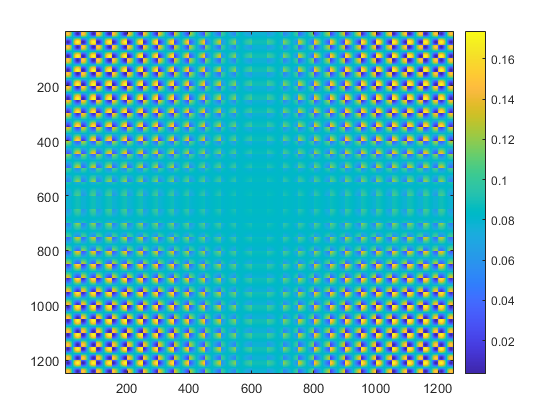

B = B';

C_B = cov(B);
imagesc(C_B)
colorbar


% 'If I reshape this^ image correctly, I should get a 4D array that varies smoothly on each of its 4 axes'
disp(['If I reshape this^ image correctly,' newline 'I should get a 4D array that ' newline 'varies smoothly on each of its 4 axes.'])

If I reshape this^ image correctly,
I should get a 4D array that 
varies smoothly on each of its 4 axes.



disp(['A good way to check if I''m reshaping it' newline 'properly or not would be to' newline 'reshape, interpolate, reshape, and plot.'])

A good way to check if I'm reshaping it
properly or not would be to
reshape, interpolate, reshape, and plot.



C = reshape(C_B,M,N,M,N);
disp('size of C')

size of C


size(C)

ans =     50    25    50    25


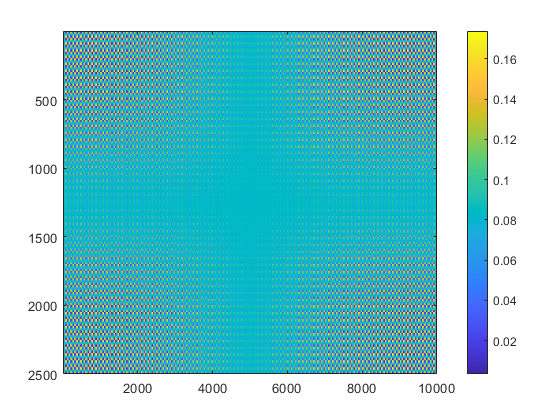


N_h = 2*N;
M_h = 2*M;

new_dom_X1 = linspace(-pi/2,pi/2,N_h);
new_dom_Y1 = linspace(-pi/2,pi/2,N_h);
new_dom_X2 = linspace(-pi/2,pi/2,M_h);
new_dom_Y2 = linspace(-pi/2,pi/2,M_h);

% [X1_h,Y1_h,X2_h,Y2_h] = ndgrid(new_dom_X1,new_dom_Y1,new_dom_X2,new_dom_Y2);
wv_i = [new_dom_X1; new_dom_Y1]; wv_j = [new_dom_X2; new_dom_Y2];

C_B_high_def = covariance_function(wv_i,wv_j,orig_dom_X1,orig_dom_Y1,C_B);

imagesc(C_B_high_def)
colorbar


disp('This is awesome and meta.')

This is awesome and meta.
